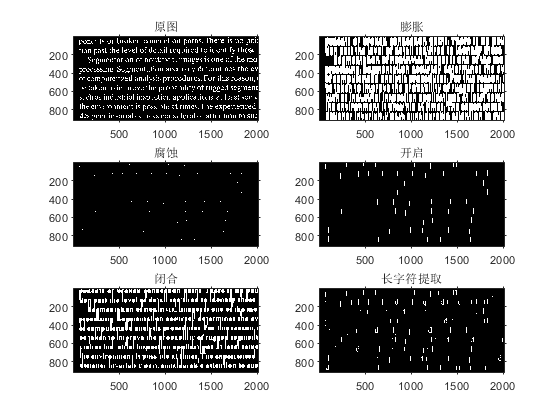

%读取图像
fig = imread("Fig1.tif");
%figure;
%imshow(fig);

%图像二值化
fig_2 = logical(fig);

%设置膨胀结构元素
E(1:51,1) = 1;

%膨胀操作
fig_d = My_dilation(fig_2,E);
figure;
subplot(421);imshow(fig_2);title("原图");axis on;
subplot(422);imshow(fig_d);title("膨胀");axis on;

%腐蚀操作
fig_e = My_erosion(fig,E);
subplot(423);imshow(fig_e);title("腐蚀");axis on;

% 先腐蚀后膨胀 => 开启
fig_ed = My_dilation(logical(My_erosion(fig,E)),E);
subplot(424);imshow(fig_ed);title("开启");axis on;

% 先膨胀后腐蚀 => 闭合
fig_de = My_erosion(logical(My_dilation(fig,E)),E);
subplot(425);imshow(fig_de);title("闭合");axis on;

%% 长字符字母提取
E2(1:51,1:3) = 1;% 膨胀结构元素
fig_get = My_getletter(fig_ed,E2,fig_2);
subplot(426);imshow(fig_get);title("长字符提取");axis on;

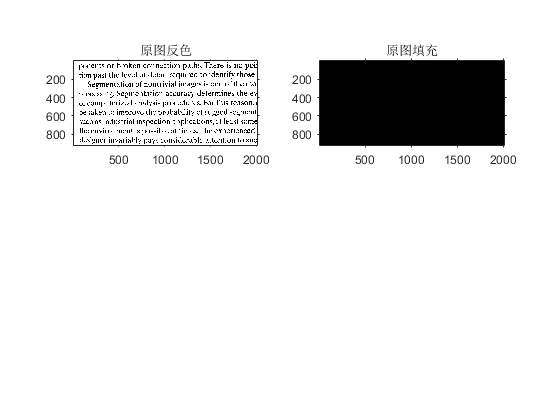


fig_n = logical(1 - fig_2);
subplot(427),imshow(fig_n);title("原图反色");axis on;

E3(1:3,1:3) = 1;
fig_fill = My_fillhole(fig_n,E3);
subplot(428),imshow(fig_fill);title("原图填充");axis on;